# Mesh Anaysis

- *Electric Circuits Virtual Labs Project*

- *Author: Zekeriya Aliyazicioglu, Dennis Dahlquist*

- *Topic: Electrical Circuit Virtual Lab*

## Introduction

Mesh analysis is another technique to analyze circuits using mesh currents as the circuit variables. To reduce the number of equations, mesh currents is used as circuit variables instead of element currents. A mesh is a loop that does not contain any other loop within it and a loop is a closed path with no node passed more than once.  Mesh analysis applies KVL to find unknown mesh currents. Every branch current and the voltage across every branch can be found after finding the mesh currents in a circuit.

Mesh analysis is only applicable to a circuit that is *planar*. A circuit is *planar* if it can be drawn in a two dimensional space without wires crossing over other wires.

## Learning Objectives

Will be able to use the mesh-current method to solve a circuit for an arbitrary network containing resistors and independent and dependent voltage and current sources with MATLAB tools. 

Will be able to write mesh-current equations for an arbitrary circuit containing resistors,  independent, and dependent voltage and current sources and find the node voltages.

## Mesh Analysis 

Mesh analysis is a method of finding all the mesh currents of a circuit . The method is based on Kirchhoff’s Voltage Law (KCL). Mesh current  can be assigned each loop and labeled as $I_1, I_2, ..., I_n$. We can write sum the voltage drops around the mesh and let that equal zero. If a mesh contains a current source, the mesh current is the same as the current from the current source with attention to direction.  A solution to the unknown mesh currents is obtained by solving the set of mesh current equations. Every branch current cen be found from meshc current and the voltage across every branch can be found by applying Ohm’s law.

### Steps to Determine Mesh Currents 

- Assign mesh current variables such as $I_1, I_2, ..., I_n$ to the n meshes 

- Identifying any known mesh current.  If a mesh contains a current source, the mesh current is the same as the current from the current source with attention to direction. We assume that any current sources exist only in one mesh. If there is a current source exists between two meshes in a circuit, we apply a **supermesh** by excluding the current source and any elements connected in series with it. 

-  Apply KVL to each unknown mesh current. 

-  Solve the resulting simultaneous equations to obtain the unknown mesh currents.

Let’s take the steps by considering the circuit below: 

- The circuit below has two independent loops. Let’s select the directions  and assign mesh current variables as $I_1$and $I_2$

                       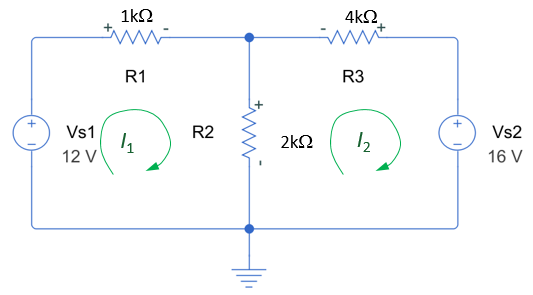

          2.   Look at the figure above to find any of the mesh currents are known. There is no any mesh contains a current source.

           4. Apply KVL to each unknown mesh current $I_1$and $I_2$

                               Loop 1 :  $-V_{s1}+R_1I_1+R_2(I_1-I_2)=0$

                               Loop 2 :   $R_2(I_2-I_1)+R_3I_2+V_{s2}=0$

      We have two equations and two unknowns. One of the methods is to use MATLAB** solve** function to find $I_1$and $I_2$  as follow.    

u = symunit;

% Given Values
Vs1 = 12*u.V;
Vs2 = 16*u.V;
R1 = 1*u.kOhm

$$R1 = \mathrm{k\Omega}$$

R2 = 2*u.kOhm

$$R2 = 2\,\mathrm{k\Omega}$$

R3 = 4000*u.Ohm

$$R3 = 4000\,\Omega$$


% Known mesh currents
% None

% Unknown mesh currents
syms I1 I2;

% Mesh equations and solutions
[I1,I2] = solve (-Vs1+R1*I1+R2*(I1-I2)==0, R2*(I2-I1)+R3*I2+Vs2==0);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = \frac{20}{7}\,\mathrm{mA}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = -\frac{12}{7}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 2.8571\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = -1.7143\,\mathrm{mA}$$

Let's try to find the each branch current and  voltages  cross the braches as assigned the the following circuit

                    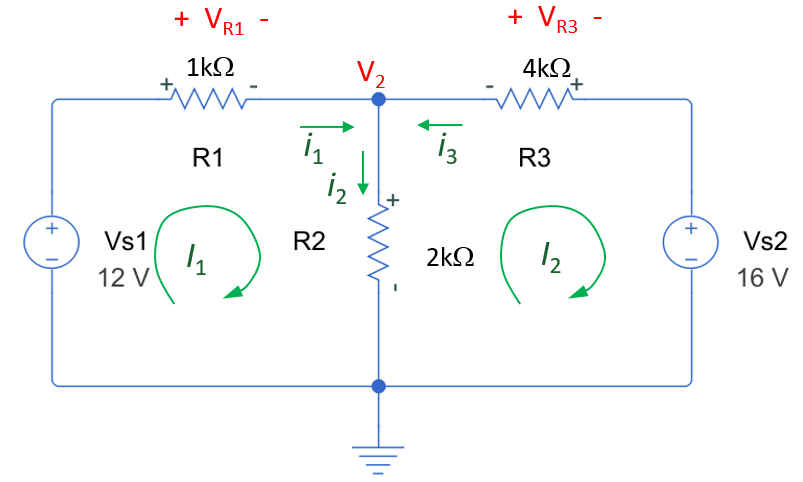

Currents through each branch

    $i_1=I_1$,    $i_2=I_1-I_2$,  and    $i_3=-I_2$

% Find branch Currents
i1 = I1; 
i2 = I1-I2; 
i3 = -I2; 

Display each values in 4 significant decimal digits

i1 = vpa(i1,5)

$$i1 = 2.8571\,\mathrm{mA}$$

i2 = vpa(i2,5)

$$i2 = 4.5714\,\mathrm{mA}$$

i3 = vpa(i3,5)

$$i3 = 1.7143\,\mathrm{mA}$$

The voltages cross each branch

   $V_{R1}=R_1i_1$,  $V_{R2}=V_2=R_2i_3$,  and $V_{R3}=R_3i_2$,  

% Find branch voltages
VR1 = R1*i1;   VR1=rewrite(VR1,u.V);    % define as V
VR2 = R2*i2;   VR2 = rewrite(VR2,u.V);  % define as V
VR3 = R3*i3;   VR3 = rewrite(VR3,u.V);  % define as V

Display each values in 4 significant decimal digits

VR1 = vpa(VR1,5)

$$VR1 = 2.8571\,V$$

VR2 = vpa(VR2,5)

$$VR2 = 9.1429\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 6.8571\,V$$

**Alternative solution**:  Last two loop equations can be solved manually with some simple algebra. Let's reorginize these loop equations as 

                             
$$(R_1+R_2)I_1-R_2I_2=V_{s1}$$


                              $-R_2I_1+(R_2+R_3)I_2=-V_{s2}$,    

          Substituting the component values               

                      
$$(1k+2k)I_1-2kI_2=12$$


                      $-2kI_1+(2k+4k)I_2=-16$,    

The equations can be rearranged  in unknown variables and put into a matrix form as

            $\left[ \begin{array} { c c } {R_1+R_2 } & {-R_2 } \\ {-R_2 } & {R_2+R_3 } \end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \end{array} \right] = \left[ \begin{array} { c } {V_{s1}} \\ {-V_{s2} } \end{array} \right]$  or              $\left[ \begin{array} { c c } {1k+2k } & {-2k} \\ {-2k } & {2k+4k } \end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \end{array} \right] = \left[ \begin{array} { c } {12} \\ {-16 } \end{array} \right]$

This matrix equation can be solved using MATLAB as shown

%Matrix AxI=b
A = [(R1+R2) -R2; -R2 (R2+R3)]

$$A = \left(\begin{array}{cc} 3\,\mathrm{k\Omega} & -2\,\mathrm{k\Omega}\\ -2\,\mathrm{k\Omega} & 4000\,\Omega +2\,\mathrm{k\Omega} \end{array}\right)$$

b = [Vs1; -Vs2]

$$b = \left(\begin{array}{c} 12\,V\\ -16\,V \end{array}\right)$$

I = A\b;

I1 = I(1);
I1 = rewrite(I1,u.mA)

$$I1 = \frac{20}{7}\,\mathrm{mA}$$

I2 = I(2)

$$I2 = -\frac{12}{6000\,\Omega +\mathrm{k\Omega}}\,V$$

I2 = rewrite(I2,u.mA)

$$I2 = -\frac{12}{7}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 2.8571\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = -1.7143\,\mathrm{mA}$$

Let's try to find the each branch current and  voltages  cross the braches as assigned the the following circuit

Currents through each branch

    $i_1=I_1$,    $i_2=I_1-I_2$,  and    $i_3=-I_2$

% Find branch Currents
i1 = I1; 
i2 = I1-I2; 
i3 = -I2; 

Display each values in 4 significant decimal digits

i1 = vpa(i1,5)

$$i1 = 2.8571\,\mathrm{mA}$$

i2 = vpa(i2,5)

$$i2 = 4.5714\,\mathrm{mA}$$

i3 = vpa(i3,5)

$$i3 = 1.7143\,\mathrm{mA}$$

The voltages cross each branch

   $V_{R1}=R_1i_1$,  $V_{R2}=V_2=R_2i_3$,  and $V_{R3}=R_3i_2$,  

% Find branch voltages
VR1 = R1*i1;   VR1 = rewrite(VR1,u.V);    % define as V
VR2 = R2*i2;   VR2 = rewrite(VR2,u.V);  % define as V
VR3 = R3*i3;   VR3 = rewrite(VR3,u.V);  % define as V

Display each values in 4 significant decimal digits

VR1 = vpa(VR1,5)

$$VR1 = 2.8571\,V$$

VR2 = vpa(VR2,5)

$$VR2 = 9.1429\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 6.8571\,V$$

Finally we have the following values

$V_{R1}=2.8571V$,   $V_{R2} = 9.1429 V$,    and $V_{R3}=6.8571V$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Mesh_Analysis_1.slx](matlab:open('./Simulink\Mesh_Analysis_1.slx'))

        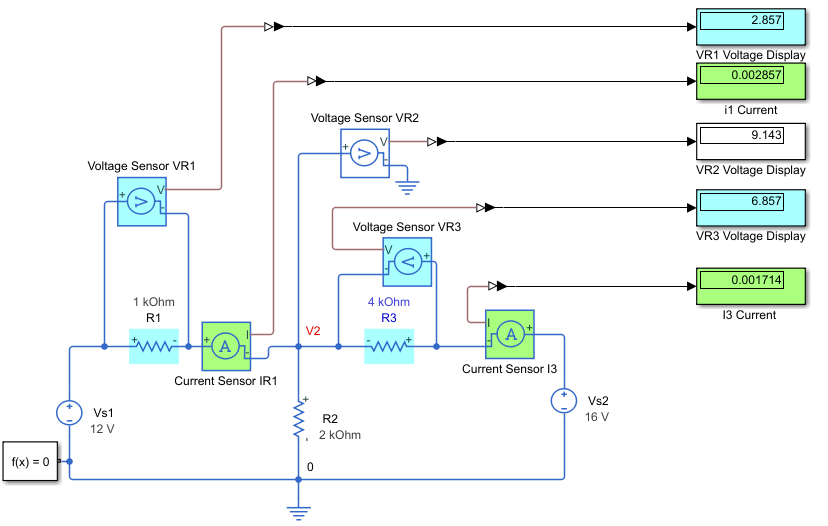

To make another simulation, we  can define the resistance values are as variables and see the effects on the node voltages and branch currents through the resistance.

u=symunit;

% Given Values
Vs1 = 12*u.V;
Vs2 = 16*u.V;
R1 = 1*u.kOhm;
R1 =3*u.kOhm %Range 1kOhms - 10kOhms

$$R1 = 3\,\mathrm{k\Omega}$$

R2 =4*u.kOhm %Range 1kOhms - 20kOhms

$$R2 = 4\,\mathrm{k\Omega}$$

R3 =4*u.kOhm %Range 1kOhms - 10kOhms

$$R3 = 4\,\mathrm{k\Omega}$$


% Known mesh currents
% None

% Unknown mesh currents
syms I1 I2;

% Mesh equations and solutions
[I1,I2] = solve (-Vs1+R1*I1+R2*(I1-I2)==0, R2*(I2-I1)+R3*I2+Vs2==0);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = \frac{4}{5}\,\mathrm{mA}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = -\frac{8}{5}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 0.8\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = -1.6\,\mathrm{mA}$$

Let's try to find the each branch current and  voltages  cross the braches as assigned the the following circuit

Currents through each branch

    $i_1=I_1$,    $i_2=I_1-I_2$,  and    $i_3=-I_2$

% Find branch Currents
i1 = I1; 
i2 = I1-I2; 
i3 = -I2; 

Display each values in 4 significant decimal digits

i1 = vpa(i1,5)

$$i1 = 0.8\,\mathrm{mA}$$

i2 = vpa(i2,5)

$$i2 = 2.4\,\mathrm{mA}$$

i3 = vpa(i3,5)

$$i3 = 1.6\,\mathrm{mA}$$

The voltages cross each branch

   $V_{R1}=R_1i_1$,  $V_{R2}=V_2=R_2i_3$,  and $V_{R3}=R_3i_2$,  

% Find branch voltages
VR1 = R1*i1;   VR1=rewrite(VR1,u.V);    % define as V
VR2 = R2*i2;   VR2 = rewrite(VR2,u.V);  % define as V
VR3 = R3*i3;   VR3 = rewrite(VR3,u.V);  % define as V

Display each values in 4 significant decimal digits

VR1 = vpa(VR1,5)

$$VR1 = 2.4\,V$$

VR2 = vpa(VR2,5)

$$VR2 = 9.6\,V$$

VR3 = vpa(VR3,5)

$$VR3 = 6.4\,V$$

### Case 1:  A circuit with contains only voltage sources. 

#### Example 1. Mesh analysis in a circuit with contains only voltage sources 

Writing Mesh analysis to find node voltages $$V_1, V_2$,  and  current through voltage source $V_{s3}$. Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

                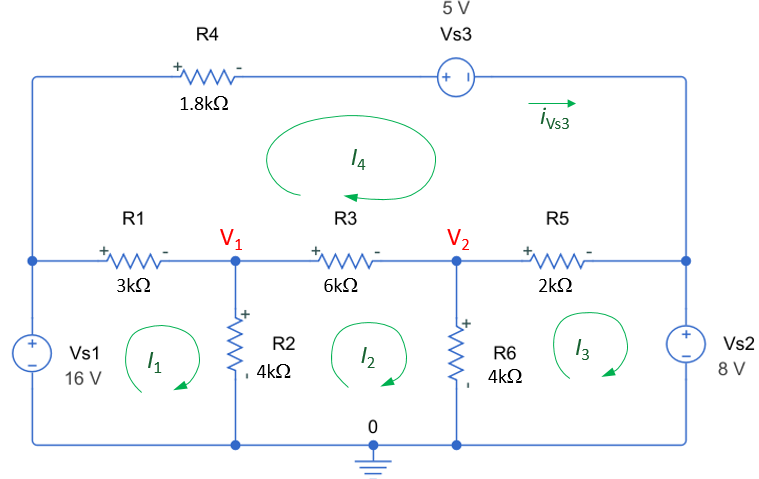

   **Solution**

    Look at the circuit above to find any of the mesh currents are known. There is no any mesh contains a current source.

    Apply KVL to each unknown mesh current $I_1, I_2, I_3$and $I_4$

                               Loop 1 :  $-V_{s1}+R_1(I_1-I_4)+R_2(I_1-I_2)=0$

                               Loop 2 :   $R_2(I_2-I_1)+R_3(I_2-I_4)+R_6(I_2-I_3)=0$

                               Loop 3 :   $R_6(I_3-I_2)+R_5(I_3-I_4)+V_{s2}=0$

                               Loop 4 :   $R_4I_4+V_{s3}+R_5(I_4-I_3)+R_3(I_4-I_2)+R_1(I_4-I_1)=0$

     We have four equations and four unknowns. One of the methods is to use MATLAB** solve** function to find $I_1, I_2, I_3$and $I_4$  as follow.    

u = symunit;

% Given Values
Vs1 = 16*u.V; Vs2 = 8*u.V; Vs3 = 5*u.V;
R1 = 3*u.kOhm; R2 = 4*u.kOhm; R3 = 6*u.kOhm; R4 = 1.5*u.kOhm; R5 = 2*u.kOhm; R6 = 4*u.kOhm;

% No known mesh currents

% Unknown mesh currents
syms I1 I2 I3 I4;

% Mesh equations and solutions
[I1,I2, I3 I4] = solve (-Vs1+R1*(I1-I4)+R2*(I1-I2)==0, R2*(I2-I1)+R3*(I2-I4)+R6*(I2-I3)==0, ...
                         R6*(I3-I2)+R5*(I3-I4)+Vs2==0, R4*I4+Vs3+R5*(I4-I3)+R3*(I4-I2)+R1*(I4-I1)==0);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = \frac{86}{19}\,\mathrm{mA}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = \frac{46}{19}\,\mathrm{mA}$$

I3 = rewrite(I3,u.mA)   % define as mA

$$I3 = \frac{18}{19}\,\mathrm{mA}$$

I4 = rewrite(I4,u.mA)   % define as mA

$$I4 = 2\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 4.5263\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 2.4211\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = 0.94737\,\mathrm{mA}$$

I4 = vpa(I4,5)

$$I4 = 2.0\,\mathrm{mA}$$

The node voltages V1 and V2 can be calculated as

        $V_1=R_2(I_1-I_2)$   ,               $V_2=R_6(I_2-I_3)$

Currents through Vs2

        $i_{Vs3}=I_4$,    

% Find Node Voltages V1 and V2
V1=R2*(I1-I2);  V1 = rewrite(V1,u.V);
V2 = R6*(I2-I3);  V2 = rewrite(V2,u.V);
iVs3= I4; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = 8.4211\,V$$

V2 = vpa(V2,5)

$$V2 = 5.8947\,V$$

iVR3 = vpa(iVs3,5)

$$iVR3 = 2.0\,\mathrm{mA}$$

**Alternative solution:** Last four loop equations can be solved manually with some simple algebra.  The equations can be rearranged  in unknown variables and put into a matrix form as

                             
$$(R_1+R_2)I_1-R_2I_2-R_1I_4=V_{s1}$$


                             $-R_2I_1+(R_2+R_3+R_6)I_2-R_6I_3-R_3I_4=0$,   

                             $-R_6I_2+(R_5+R_6)I_3-R_5I_4=-V_{s2}$,   

                              $-R_2I_1-R_3I_2-R_5I_3+(R_1+R_3+R_4+R_5)I_4=-V_{s3}$,  

                        
$$\left[ \begin{array} { c c  c  c } {R_1+R_2 } & {-R_2 } & 0 & -R_1\\ {-R_2 } & {R_2+R_3+R_6 } & {-R_6} & {-R_3}\\ {0} & {R_6} & {R_5+R_6} & {R_5} \\ {-R_1} & {-R_3} & {-R_5} & {R_1+R_3+R_4+R_5} \end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \\{I_3}\\ {I_4} \end{array} \right] = \left[ \begin{array} { c } {V_{s1}} \\ {0 } \\{-V_{s2}} \\ {-V_{s3}}\end{array} \right]$$
  

This matrix equation can be solved using MATLAB as shown

%Matrix AxI=b
A = [(R1+R2) -R2 0 -R1; -R2 (R2+R3+R6) -R6 -R3; 0 R6 R5+R6 R5; -R1 -R3 -R5 (R1+R3+R4+R5)]

$$A = \begin{array}{l} \left(\begin{array}{cccc} 7\,\mathrm{k\Omega} & \sigma_{1} & 0 & -3\,\mathrm{k\Omega}\\ \sigma_{1} & 14\,\mathrm{k\Omega} & \sigma_{1} & -6\,\mathrm{k\Omega}\\ 0 & 4\,\mathrm{k\Omega} & 6\,\mathrm{k\Omega} & 2\,\mathrm{k\Omega}\\ -3\,\mathrm{k\Omega} & -6\,\mathrm{k\Omega} & -2\,\mathrm{k\Omega} & \frac{25}{2}\,\mathrm{k\Omega} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-4\,\mathrm{k\Omega} \end{array}$$

b = [Vs1; 0; -Vs2;Vs3]

$$b = \left(\begin{array}{c} 16\,V\\ 0\\ -8\,V\\ 5\,V \end{array}\right)$$

I = A\b;

I1 = I(1);    I1 = rewrite(I1,u.mA)

$$I1 = \frac{8902}{2733}\,\mathrm{mA}$$

I2 = I(2);    I2 = rewrite(I2,u.mA)

$$I2 = \frac{2182}{2733}\,\mathrm{mA}$$

I3 = I(3);    I3 = rewrite(I3,u.mA)

$$I3 = -\frac{6194}{2733}\,\mathrm{mA}$$

I4 = I(4);    I4 = rewrite(I4,u.mA)

$$I4 = \frac{3286}{2733}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 3.2572\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 0.79839\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = -2.2664\,\mathrm{mA}$$

I4 = vpa(I4,5)

$$I4 = 1.2023\,\mathrm{mA}$$

Let's find the V1 and V2

        $V_1=R_2(I_1-I_2)$   ,               $V_2=R_6(I_2-I_3)$

Currents through Vs2

    $i_{Vs2}=I4$,    

% Find Node Voltages V1 and V2
V1=R2*(I1-I2);  V1 = rewrite(V1,u.V);
V2 = R6*(I2-I3);  V2 = rewrite(V2,u.V);
iVs3= I4; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = 9.8353\,V$$

V2 = vpa(V2,5)

$$V2 = 12.259\,V$$

iVs3 = vpa(iVs3,5)

$$iVs3 = 1.2023\,\mathrm{mA}$$

Finally we have the following values

$V_1=9.8353V$,   $V_2 =12.259 V$,    and $i_{Vs3}=1.2023 mA$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_1.slx](matlab:open('./Simulink\Example_1.slx'))

        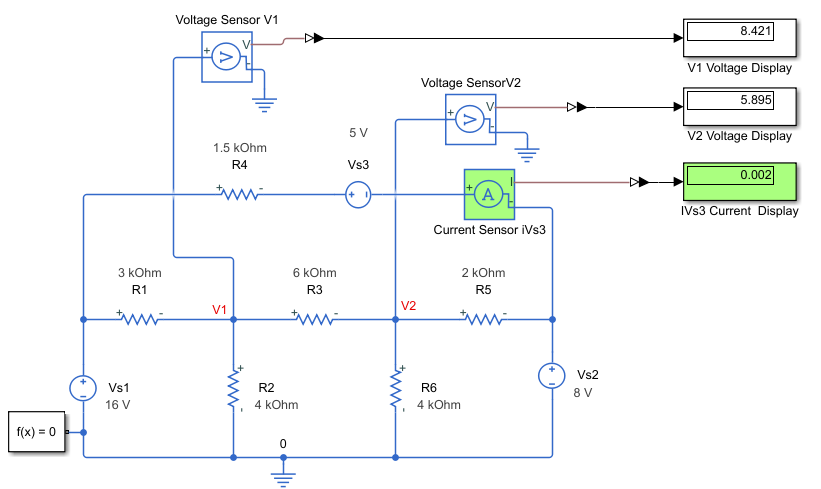

#### Exercise 1. Mesh analysis in a circuit with contains only voltage source

-  Writing Mesh analysis to find $$V_1, V_2$, and  currents through sourcses $V_{s3}$ and $V_{s4}$. Solve the problem in MATLAB Script. Simulate the circuit in Simulink to verify our results. 

- If Voltage sources $V_{s1}$changes to 30V and $V_{s2}$changes to 10V, what will be the value of node voltages $$V_1, V_2$, and  current through source $V_{s3}$ and $V_{s4}$

                        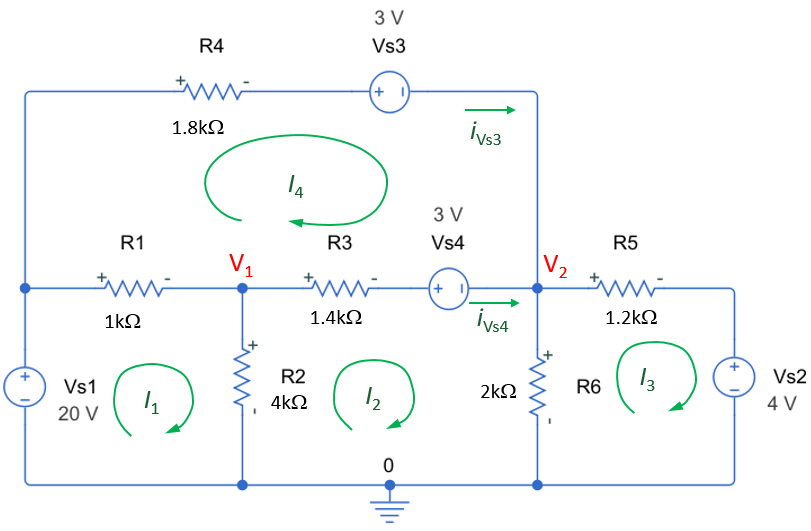

**Solution Steps:**    

 Look at the circuit above to find any of the mesh currents are known. (Is there any mesh contains a current source?)

      Apply KVL to each unknown mesh current $I_1, I_2, I_3$and $I_4$

                               Loop 1 :  

                               Loop 2 :   

                               Loop 3 :   

                               Loop 4 :   

      Use MATLAB** solve** function to find $I_1, I_2, I_3$and $I_4$  as follow.    

u = symunit;

% Given Values
% Vs1 =10*u.V   %Range 10V - 30V
% Vs2 =10*u.V   % Range 2V - 10V
% Vs3 = ??*u.V; Vs4 = ??*u.V; .... Voltage sources
% R1 = ??*u.kOhm; R2 = ??*u.kOhm; .... Reistances

% Any known mesh current

% Unknown mesh currents
syms I1 I2 I3 I4;

% Mesh equations and solutions
%[I1,I2, I3 I4] = solve (??);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = I_{1}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = I_{2}$$

I3 = rewrite(I3,u.mA)   % define as mA

$$I3 = I_{3}$$

I4 = rewrite(I4,u.mA)   % define as mA

$$I4 = I_{4}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = I_{1}$$

I2 = vpa(I2,5)

$$I2 = I_{2}$$

I3 = vpa(I3,5)

$$I3 = I_{3}$$

I4 = vpa(I4,5)

$$I4 = I_{4}$$

Find the node voltages  $V_1$  and $V_2$ 

Find the currents through $V_{s3}$ and $V_{s4}$

Write in MATLAB to find the values  

% Find Node Voltages V1 and V2
% V1=?;  V1 = rewrite(V1,u.V)
% V2 = ?;  V2 = rewrite(V2,u.V)
% iVs3= ?; 
% iVs4= ?; 

Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% iVs3 = vpa(iVs3,5)
% iVs4 = vpa(iVs4,5)

Change $V_{s1}=30V$ and $V_{s2}=10V$ and find the values of node voltages $$V_1, V_2$, and  currents through source $V_{s3}$ and $V_{s4}$. 

**Alternative solution**: Reorginize these loop equations as as function of $I_1, I_2, I_3$ and $I_4$

  Write in a matrix form as

            
$$\left[ \begin{array} { c c  c  c } {? } & {?} & ? &?\\ {? } & {?} & {?} & {?}\\ {?} & {?} & {?} & {?} \\ {?} & {?} & {?} & {?} \end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \\{I_3}\\ {I_4} \end{array} \right] = \left[ \begin{array} { c } {?} \\ {? } \\{?} \\ {?}\end{array} \right]$$
  

Solve this matrix equation using MATLAB 

% Matrix AxI=b
% A = [??]
% b = [??]
% I = A\b;

% I1 = I(1);    I1 = rewrite(I1,u.mA)
% I2 = I(2);    I2 = rewrite(I2,u.mA)
% I3 = I(3);    I3 = rewrite(I3,u.mA)
% I4 = I(4);    I4 = rewrite(I4,u.mA)

Display each values in 4 significant decimal digits

% I1 = vpa(I1,5)
% I2 = vpa(I2,5)
% I3 = vpa(I3,5)
% I4 = vpa(I4,5)

Find the node voltages  $V_1$  and $V_2$

Find the currents through $V_{s3}$ and $V_{s4}$

Write in MATLAB to find the values  

% Find Node Voltages V1 and V2
% V1=??;  V1 = rewrite(V1,u.V);
% V2 = ??;  V2 = rewrite(V2,u.V);
% iVs3= ??;
% iVs4= ??;

Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% iVs3 = vpa(iVs3,5)
% iVs4 = vpa(iVs4,5)

Final values are :  ??

Simulate  this exercise using MATLAB Simulink to chek your values.    

        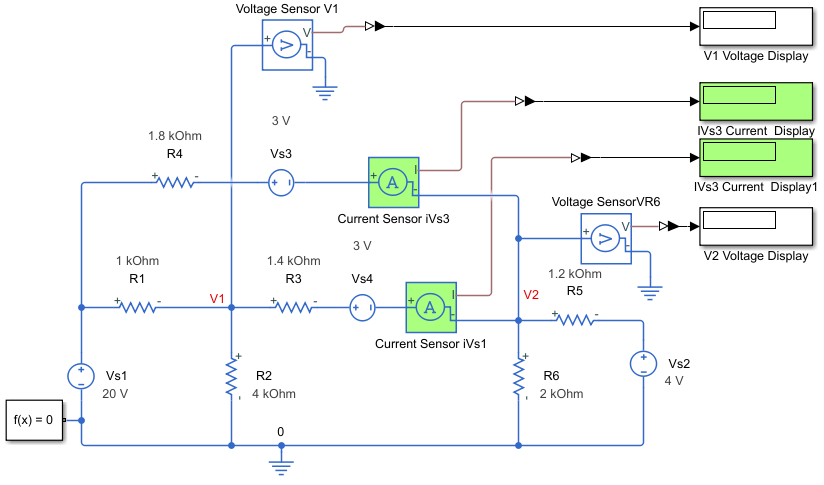

### Case 2:  Current Sources Exist Only in one Mesh.

If a mesh contains a current source, the mesh current is the same as the current from the current source with attention to direction.

#### Example 2.  Mesh analysis with current sources exists only in one Mesh

- Using mesh analysis to find node voltages $$V_1, V_2, V_3$, voltage $$V_{R_4}$ cross resistor  $R_4$ , and  current through $R_4$

- Find node voltages $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_1$,  current through $R_4$ when the voltage source $V_{s1}=32V$

- Find node voltages $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_1$,  current through $R_4$ when the current source $I_{s1}=0.5mA$

                  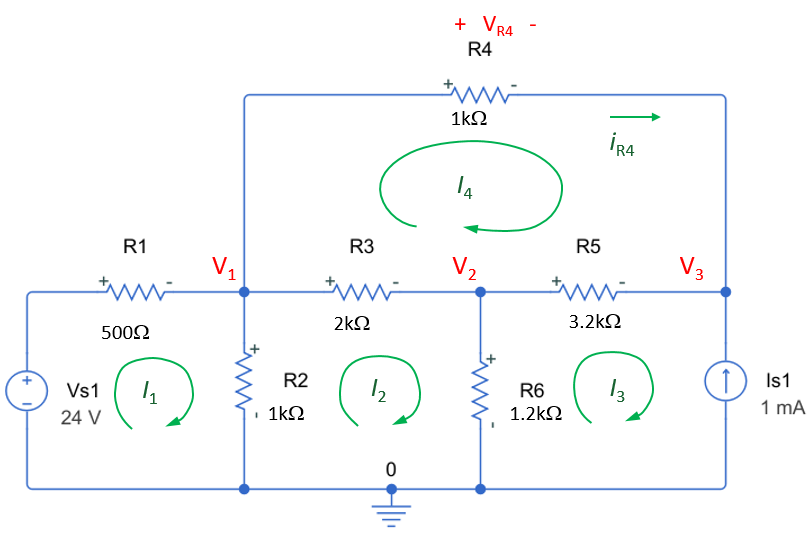

 **Solution**

    Look at the circuit above to find any of the mesh currents are known. 

                    
$$I_3=-I_{S1}=-1mA$$


      Apply KVL to each unknown mesh current $I_1, I_2$and $I_4$

                               Loop 1 :  $-V_{s1}+R_1I_1+R_2(I_1-I_2)=0$

                               Loop 2 :   $R_2(I_2-I_1)+R_3(I_2-I_4)+R_6(I_2-I_3)=0$

                               Loop 4 :   $R_4I_4+R_5(I_4-I_3)+R_3(I_4-I_2)+=0$

      We have four equations and four unknowns. One of the methods is to use MATLAB** solve** function to find $I_1, I_2$and $I_4$  as follow.    

u = symunit;

% Given Values
Vs1 =22*u.V   %Range 10V - 40V

$$Vs1 = 22\,V$$

Is1 =0.9*u.mA   %Range 0.5mA - 2mA

$$Is1 = \frac{9}{10}\,\mathrm{mA}$$

% Vs1 = 24*u.V; Is1=1*u.mA;
R1 = 500*u.Ohm; R2 = 1*u.kOhm; R3 = 2*u.kOhm; R4 = 1*u.kOhm; R5 = 3.2*u.kOhm;R6 = 1.2*u.kOhm;

% Known mesh currents
I3 = -Is1;
% Unknown mesh currents
syms I1 I2 I4;

% Mesh equations and solutions
[I1,I2, I4] = solve (-Vs1+R1*(I1)+R2*(I1-I2)==0, R2*(I2-I1)+R3*(I2-I4)+R6*(I2-I3)==0, ...
                         R4*I4+R5*(I4-I3)+R3*(I4-I2)==0);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = \frac{118106}{6715}\,\mathrm{mA}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = \frac{29429}{6715}\,\mathrm{mA}$$

I4 = rewrite(I4,u.mA)   % define as mA

$$I4 = \frac{6374}{6715}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 17.588\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 4.3826\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = -0.9\,\mathrm{mA}$$

I4 = vpa(I4,5)

$$I4 = 0.94922\,\mathrm{mA}$$

Let's find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

        $V_1=R_2(I_1-I_2)$   ,   $V_2=R_6(I_2-I_3)$, $V_3=V_2-R_5(I_3-I_4)$,  and  $V_{R4}=R_4I_4$

Current through $R_4$

    $i_{R4}=I_4$,    

% Find Node Voltages V1, V2, V4, and VR4 voltage cross resitance R4 
V1 = R2*(I1-I2);  V1 = rewrite(V1,u.V);
V2 = R6*(I2-I3);  V2 = rewrite(V2,u.V);
V3 = V2-R5*(I3-I4);  V3 = rewrite(V3,u.V);
VR4 = R4*I4;    VR4 = rewrite(VR4,u.V);
% Current through R4
iR4 = I4; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = 13.206\,V$$

V2 = vpa(V2,5)

$$V2 = 6.3391\,V$$

V3 = vpa(V3,5)

$$V3 = 12.257\,V$$

VR4 = vpa(VR4,5)

$$VR4 = 0.94922\,V$$

iR4 = vpa(iR4,5)

$$iR4 = 0.94922\,\mathrm{mA}$$

**Alternative solution**: Last four loop equations can be solved manually with some simple algebra.   The equations can be rearranged  in unknown variables and put into a matrix form as

                             
$$(R_1+R_2)I_1-R_2I_2=V_{s1}$$


                             $-R_2I_1+(R_2+R_3+R_6)I_2-R_3I_4=R_6I_3$,   

                             $-R_3I_2+(R_3+R_4+R_5)I_4=R_5I_3$,    

                        
$$\left[ \begin{array} { c c  c  } {R_1+R_2 } & {-R_2 } & 0 \\ {-R_2 } & {R_2+R_3+R_6 } &  {-R_3} \\ {0} & {-R_3} & {R_3+R_4+R_5} \end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \\{I_4} \end{array} \right] = \left[ \begin{array} { c } {V_{s1}} \\ {R_6I_3 } \\{R_5I_3} \end{array} \right]$$
  

This matrix equation can be solved using MATLAB as shown

%Matrix AxI=b
A = [(R1+R2) -R2 0 ; -R2 (R2+R3+R6) -R3; 0 -R3 (R3+R4+R5)];
A=simplify (A)

$$A = \left(\begin{array}{ccc} \frac{3}{2}\,\mathrm{k\Omega} & -1\,\mathrm{k\Omega} & 0\\ -1\,\mathrm{k\Omega} & \frac{21}{5}\,\mathrm{k\Omega} & -2\,\mathrm{k\Omega}\\ 0 & -2\,\mathrm{k\Omega} & \frac{31}{5}\,\mathrm{k\Omega} \end{array}\right)$$

A=vpa(A)

$$A = \left(\begin{array}{ccc} 1.5\,\mathrm{k\Omega} & -1.0\,\mathrm{k\Omega} & 0\\ -1.0\,\mathrm{k\Omega} & 4.2\,\mathrm{k\Omega} & -2.0\,\mathrm{k\Omega}\\ 0 & -2.0\,\mathrm{k\Omega} & 6.2\,\mathrm{k\Omega} \end{array}\right)$$

b = [Vs1; R6*I3; R5*I3];
b=vpa(b,5)

$$b = \left(\begin{array}{c} 22.0\,V\\ -1.08\,\mathrm{k\Omega}\,\mathrm{mA}\\ -2.88\,\mathrm{k\Omega}\,\mathrm{mA} \end{array}\right)$$

I = A\b;

I1 = I(1);    I1 = rewrite(I1,u.mA);
I2 = I(2);    I2 = rewrite(I2,u.mA);
I4 = I(3);    I4 = rewrite(I4,u.mA);

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 17.588\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 4.3826\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = -0.9\,\mathrm{mA}$$

I4 = vpa(I4,5)

$$I4 = 0.94922\,\mathrm{mA}$$

Let's find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

        $V_1=R_2(I_1-I_2)$   ,   $V_2=R_6(I_2-I_3)$, $V_3=V_2-R_5(I_3-I_4)$,  and  $V_{R4}=R_4I_4$

Currents through R4

    $i_{R4}=I_4$,    

% Find Node Voltages V1, V2, V3 and Voltage cross R4
V1=R2*(I1-I2);  V1 = rewrite(V1,u.V);
V2 = R6*(I2-I3);  V2 = rewrite(V2,u.V);
V3 = V2-R5*(I3-I4);  V3 = rewrite(V3,u.V);
VR4=R4*I4;    VR4 = rewrite(VR4,u.V);
% Find current through R4
iR4= I4; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = 13.206\,V$$

V2 = vpa(V2,5)

$$V2 = 6.3391\,V$$

V3 = vpa(V3,5)

$$V3 = 12.257\,V$$

VR4 = vpa(VR4,5)

$$VR4 = 0.94922\,V$$

iR4 = vpa(iR4,5)

$$iR4 = 0.94922\,\mathrm{mA}$$

Finally we have the following values

$V_1=14.411V$,   $V_2 =6.9203 V$,  $V_3 =13.389 V$  , $V_{R4} =1.0216 V$and $i_{R4}=1.0206mA$

Circuit can be simulated  in MATLAB Simulink [./Simulink\Example_2.slx](matlab:open('./Simulink\Example_2.slx'))

        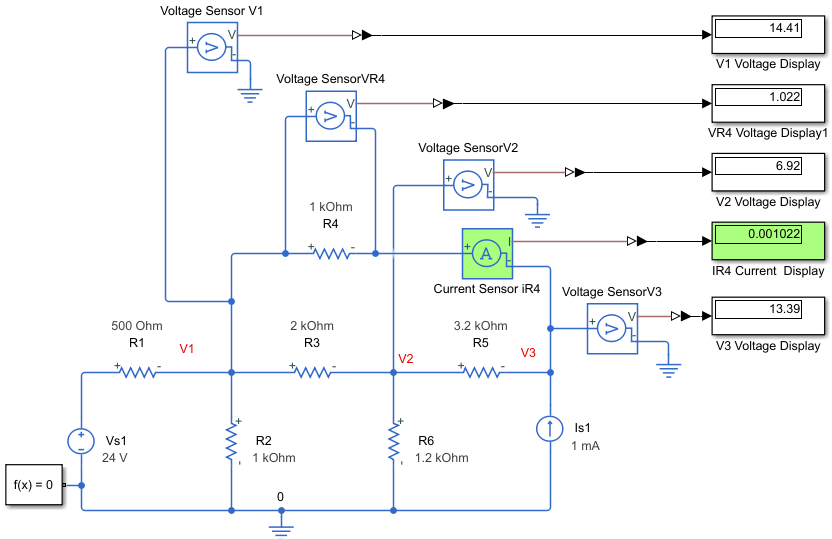

#### Exercise 2: Mesh analysis with current sources exists only in one Mesh

- Using mesh analysis to find node voltages $$V_1, V_2, V_3$, voltage $$V_{R_4}$ cross resistor  $R_4$ , and  current through $R_4$

- Find node voltages $$V_2, V_3, V_4$, and voltage $$V_{R_4}$ cross resistor  $R_1$,  current through $R_4$ when reistance $R_4=2k\Omega$

             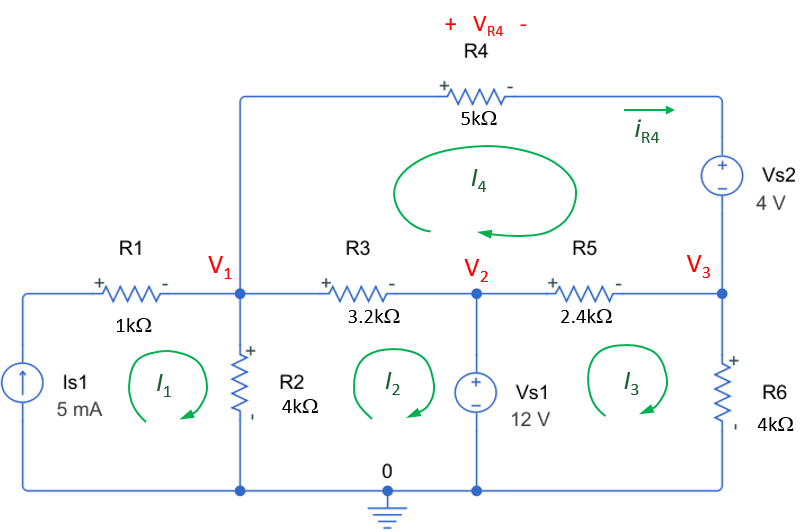

**Solution**

    Look at the circuit above to find any of the mesh currents are known. 

    Apply KVL to each unknown mesh current $I_2, I_3$and $I_4$

                               Loop 2 :  

                               Loop 3 :   

                               Loop 4 :   

      Use MATLAB** solve** function to find $I_2, I_3$and $I_4$  as follow.    

u = symunit;

% Given Values


% Known  mesh currents

% Unknown mesh currents
syms I2 I3 I4;

% Mesh equations and solutions
% [I2,I3, I4] = solve ( ?? );
% I2 = rewrite(I2,u.mA)   % define as mA
% I3 = rewrite(I3,u.mA)   % define as mA
% I4 = rewrite(I4,u.mA)   % define as mA

Display each values in 4 significant decimal digits

% I1 = vpa(I1,5)
% I2 = vpa(I2,5)
% I3 = vpa(I3,5)
% I4 = vpa(I4,5)

Find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

Find the current through $R_4$

% Node Voltages V1, V2, V3 and Voltage cross R4

%Current through R4


Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% VR4 = vpa(VR4,5)
% iR4 = vpa(iR4,5)

**Alternative solution**: Last four loop equations can be solved manually with some simple algebra.   The equations can be rearranged  in unknown variables and put into a matrix form as

                        
$$\left[ \begin{array} { c c  c  } {? } & {? } & ? \\ {? } & {? } &  {?} \\ {?} & {?} & {?} \end{array} \right] \left[ \begin{array} { l } { I _ 2 } \\ { I _ 3 } \\{I_4} \end{array} \right] = \left[ \begin{array} { c } {?} \\ {?} \\{?} \end{array} \right]$$
  

This matrix equation can be solved using MATLAB as shown

%Matrix AxI=b


% I2 = I(1);    I1 = rewrite(I1,u.mA);
% I3 = I(2);    I2 = rewrite(I2,u.mA);
% I4 = I(3);    I4 = rewrite(I4,u.mA);

Display each values in 4 significant decimal digits

% I1 = vpa(I1,5)
% I2 = vpa(I2,5)
% I3 = vpa(I3,5)
% I4 = vpa(I4,5)

Find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

Currents through  $R_4$

% Find Node Voltages V1, V2, V3 and Voltage cross R4

% Find current through R4


Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% VR4 = vpa(VR4,5)
% iR4 = vpa(iR4,5)

Finally we have the following values

$V_1=?$,   $V_2 =?$,  $V_3 =?$  , $V_{R4} =?$and $i_{R4}=?$

Simulate  this exercise using MATLAB Simulink to chek your values. 

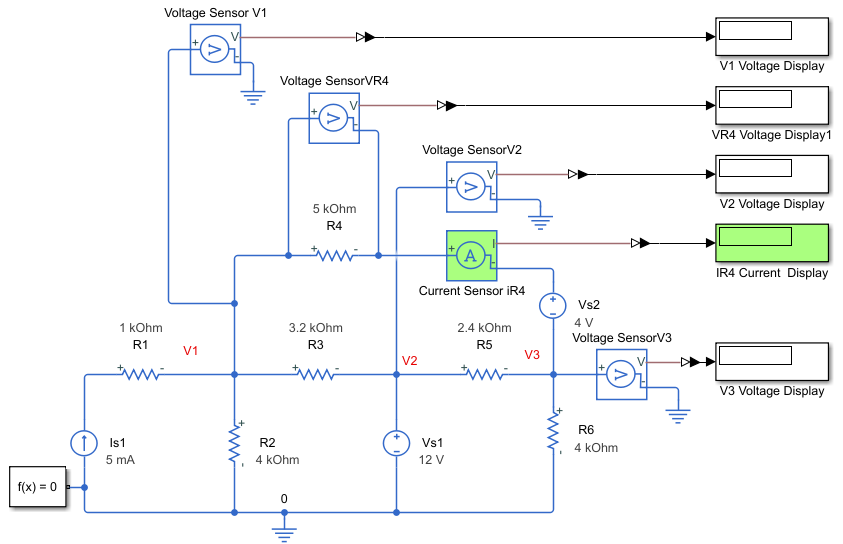

### **Case 3 :** A current source exists between two meshes (**Supermesh)**

If a current source (dependent or independent) exists between two meshes, we need to create a supermesh by excluding the current souce and any elements connected in series with it. The reason is that mesh analysis applies KVL, which requires that the voltage across each branch can be calculated  but we do not know the voltage across a current source in advance. That is the reason we  create a supermesh that  must satisfy KVL like any other mesh.   

#### Example 3. A current source exists between two meshes

Use mesh analysis to find the node voltages $V_1,  V_2, V_3$,  voltage $V_{Is1}$ across the current source $I_{s1}$, and $i_{R4}$  in the circuit shown

                        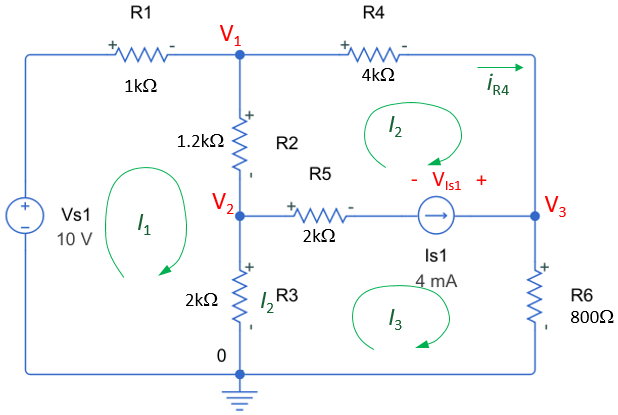

   **Solution:**       Look at the circuit above and  find out that two meshes having a current source in common. We need to create a supermesh by excluding the current source as given below with dash line.  

                         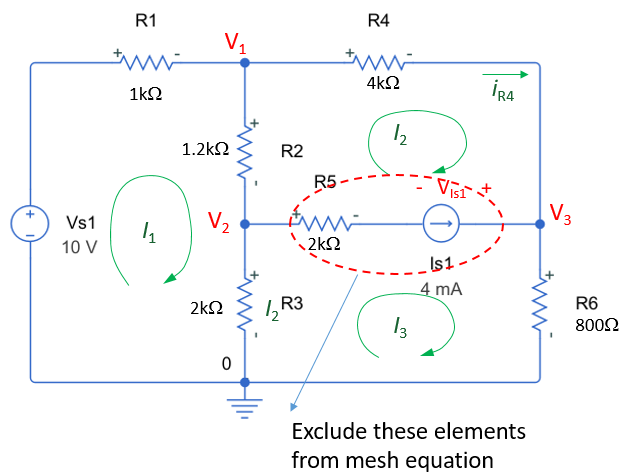 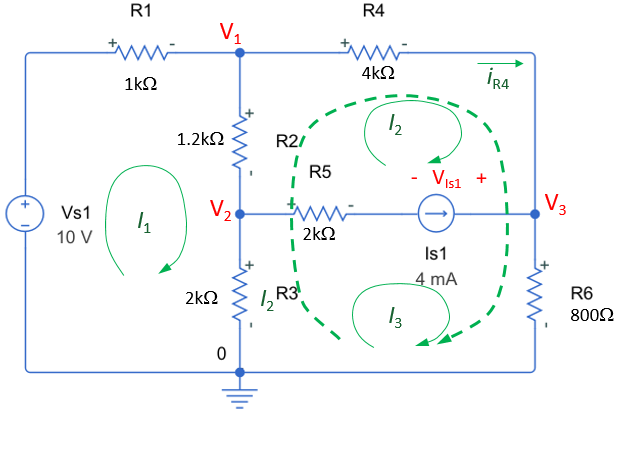

      Apply KVL to loop 1 and supermesh

                               Loop 1       :  $-V_{s1}+R_1I_1+R_2(I_1-I_2)+R_3(I_1-I_3)=0$

                              Supermesh :   $R_3(I_3-I_1)+R_2(I_2-I_1)+R_4I_2+R_6I_3=0$

       We apply KCL to a node in the branch where the two meshes intersect. Applying KCL to node V3, which gives  $I_{s1}+I_2-I_3=0$

      We have three equations and three unknowns. Use MATLAB** solve** function to find $I_1, I_2$and $I_3$  as follow.    

clear all

u = symunit;

% Given Values
Vs1 =10*u.V;   Is1 =4*u.mA  

$$Is1 = 4\,\mathrm{mA}$$

R1 = 1.2*u.kOhm; R2 = 1.2*u.kOhm; R3 = 2*u.kOhm; R4 = 4*u.kOhm; R5 = 2*u.kOhm;R6 = 800*u.Ohm;

% Known mesh currents

% Unknown mesh currents
syms I1 I2 I3;

% Mesh equations, KCL equation, and solutions
[I1,I2, I3] = solve (-Vs1+R1*(I1)+R2*(I1-I2)+R3*(I1-I3)==0, R3*(I3-I1)+R2*(I2-I1)+R4*I2+R6*I3==0, Is1+I2-I3==0);
I1 = rewrite(I1,u.mA)   % define as mA

$$I1 = \frac{13}{3}\,\mathrm{mA}$$

I2 = rewrite(I2,u.mA)   % define as mA

$$I2 = \frac{1}{3}\,\mathrm{mA}$$

I3 = rewrite(I3,u.mA)   % define as mA

$$I3 = \frac{13}{3}\,\mathrm{mA}$$

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 4.3333\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 0.33333\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = 4.3333\,\mathrm{mA}$$

Let's find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

        $V_1=V_{s1}-R_1*I_1$   ,   $V_2=R_3(I_1-I_3)$,   $V_2=R_6I_3$,  $V_{is1}=V_2-[R_5(I_3-I_2)-V_2]$,

Current through $R_4$

        $i_{R4}=I_2$,    

% Find Node Voltages V1, V2, V4, and VR4 voltage cross resitance R4 
V1 = Vs1-R1*I1;   V1 = rewrite(V1,u.V); 
V2 = R3*(I1-I3);  V2 = rewrite(V2,u.V);
V3 = R6*I3;       V3 = rewrite(V3,u.V);
Vis1 = V2-(R5*(I3-I2)+V3);    Vis1 = rewrite(Vis1,u.V);
% Current through R4
iR4 = I2; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = \left(4.8-1.6693e-39\,\mathrm{i}\right)\,V$$

V2 = vpa(V2,5)

$$V2 = 0.0$$

V3 = vpa(V3,5)

$$V3 = 3.4667\,V$$

Vis1 = vpa(Vis1,5)

$$Vis1 = \left(-11.467-3.6809e-39\,\mathrm{i}\right)\,V$$

iR4 = vpa(iR4,5)

$$iR4 = 0.33333\,\mathrm{mA}$$

**Alternative solution**: Last three loop equations can be solved manually with some simple algebra.   The equations can be rearranged  in unknown variables and put into a matrix form as

                             
$$(R_1+R_2+R_3)I_1-R_2I_2-R_3I_3=V_{s1}$$


                             $-(R_2+R_3)I_1+(R_2+R_4)I_2+(R_3+R_6)I_3=0$,   

                             
$$I_2-I_3=-I_{s1}$$


                        
$$\left[ \begin{array} { c c  c  } {R_1+R_2+R_3 } & {-R_2 } & {-R_3} \\ {-(R_2+R_3) } & {R_2+R_4 } &  {R_3+R_6} \\ {0} &{1} & {-1}{\end{array} \right] \left[ \begin{array} { l } { I _ 1 } \\ { I _ 2 } \\{I_4} \end{array} \right] = \left[ \begin{array} { c } {V_{s1}} \\ {0 } \\{-Is1} \end{array} \right]$$
  

This matrix equation can be solved using MATLAB as shown

%Matrix AxI=b
A = [R1+R2+R3 -R2 -R3 ; -(R2+R3) R2+R4 R3+R6; 0 1 -1];
A=simplify (A)

$$A = \left(\begin{array}{ccc} \frac{22}{5}\,\mathrm{k\Omega} & -\frac{6}{5}\,\mathrm{k\Omega} & -2\,\mathrm{k\Omega}\\ -\frac{16}{5}\,\mathrm{k\Omega} & \frac{26}{5}\,\mathrm{k\Omega} & \frac{14}{5}\,\mathrm{k\Omega}\\ 0 & 1 & -1 \end{array}\right)$$

A=vpa(A)

$$A = \left(\begin{array}{ccc} 4.4\,\mathrm{k\Omega} & -1.2\,\mathrm{k\Omega} & -2.0\,\mathrm{k\Omega}\\ -3.2\,\mathrm{k\Omega} & 5.2\,\mathrm{k\Omega} & 2.8\,\mathrm{k\Omega}\\ 0 & 1.0 & -1.0 \end{array}\right)$$

b = [Vs1; 0; -Is1];
b=vpa(b,5)

$$b = \left(\begin{array}{c} 10.0\,V\\ 0\\ -4.0\,\mathrm{mA} \end{array}\right)$$

I = A\b;

I1 = I(1);    I1 = rewrite(I1,u.mA)

$$I1 = 4.3333333333333333333333333333333\,\mathrm{mA}$$

I2 = I(2);    I2 = rewrite(I2,u.mA);
I3 = I(3);    I3 = rewrite(I3,u.mA);

Display each values in 4 significant decimal digits

I1 = vpa(I1,5)

$$I1 = 4.3333\,\mathrm{mA}$$

I2 = vpa(I2,5)

$$I2 = 0.33333\,\mathrm{mA}$$

I3 = vpa(I3,5)

$$I3 = 4.3333\,\mathrm{mA}$$

Let's find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

        $V_1=V_{s1}-R_1*I_1$   ,   $V_2=R_3(I_1-I_3)$,   $V_2=R_6I_3$,  $V_{is1}=V_2-[R_5(I_3-I_2)+V_2]$,

Current through $R_4$

        $i_{R4}=I_2$,    

% Find Node Voltages V1, V2, V4, and VR4 voltage cross resitance R4 
Vs1

$$Vs1 = 10\,V$$

R1

$$R1 = \frac{6}{5}\,\mathrm{k\Omega}$$

I1

$$I1 = 4.3333\,\mathrm{mA}$$

R2

$$R2 = \frac{6}{5}\,\mathrm{k\Omega}$$


V1 = Vs1-R1*I1

$$V1 = 10\,V-5.2\,\mathrm{k\Omega}\,\mathrm{mA}$$

V1 = rewrite(V1,u.V)

$$V1 = \left(4.8-1.6692563166812205956164515859455e-39\,\mathrm{i}\right)\,V$$


V2 = R3*(I1-I3)

$$V2 = -4.487878739702132696611060319682e-33\,\mathrm{k\Omega}\,\mathrm{mA}$$

V2 = rewrite(V2,u.V)

$$V2 = \left(-4.487878739702132696611060319682e-33-1.440657679759065459731234838281e-72\,\mathrm{i}\right)\,V$$

V3 = R6*I3;       V3 = rewrite(V3,u.V);
Vis1 = V2-(R5*(I3-I2)+V3);    Vis1 = rewrite(Vis1,u.V);
% Current through R4
iR4 = I2; 

Display each values in 4 significant decimal digits

V1 = vpa(V1,5)

$$V1 = \left(4.8-1.6693e-39\,\mathrm{i}\right)\,V$$

V2 = vpa(V2,5)

$$V2 = \left(-4.4879e-33-1.4407e-72\,\mathrm{i}\right)\,V$$

V3 = vpa(V3,5)

$$V3 = 3.4667\,V$$

Vis1 = vpa(Vis1,5)

$$Vis1 = \left(-11.467-1.4552e-39\,\mathrm{i}\right)\,V$$

iR4 = vpa(iR4,5)

$$iR4 = 0.33333\,\mathrm{mA}$$

Finally we have the following values

$V_1=5.37V$,   $V_2 =0.35616 V$,  $V_3 =3.5616 V$  , $V_{is1} =11.205 V$and $i_{R4}=0.45205mA$

Circuit simulation is given in the following MATLAB Simulink  [./Simulink\Example_3.slx](matlab:open('./Simulink\Example_3.slx'))

    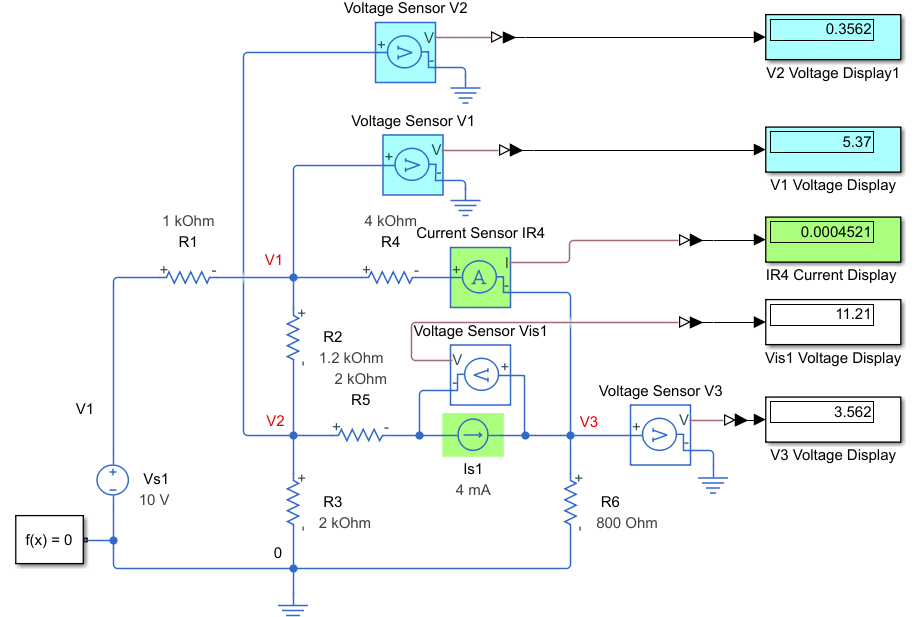

#### Exercise 3. A current source exists between two meshes (**Supermesh)** 

Using mesh analysis to find $$V_1, V_2, V_3$, and voltage $$V_{R_5}$ cross resistor  $R_5$ , and  current  $i_6 $  

                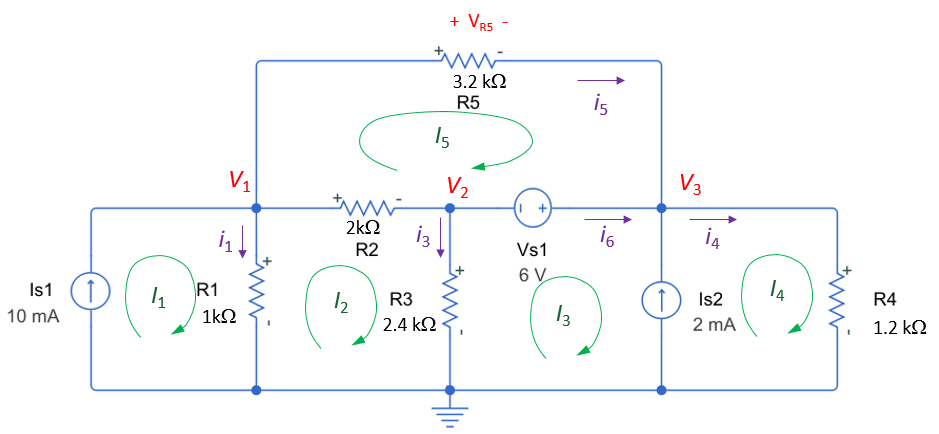

   **Solution steps:**       

        1. Look at the circuit above to find any of the mesh currents are known. 

        2. Look at the circuit  and  find out that two meshes having a current source in common. If there is, then create a supermesh by excluding the current source as given below with dash line.  

        3. Apply KVL to rest of the loop  and supermesh

        4. We apply KCL to a node in the branch where the two meshes intersect. 

        5. Use MATLAB** solve** function to find $I_1, I_2$and $I_3$  as follow.    

% u = symunit;

% Given Values


% Known mesh currents

% Unknown mesh currents
% syms ???;

% Mesh equations, KCL equation, and solutions


       6. Display each values in 4 significant decimal digits

%  I1 = vpa(I1,5)
% ??

     7. Find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

    8. Current through $R_4$

    9. Write in MATLAB code  

% Find Node Voltages V1, V2, V4, and VR4 voltage cross resitance R4 
% V1 = ??;   V1 = rewrite(V1,u.V); 
% V2 = ??;  V2 = rewrite(V2,u.V);
% V3 =??;       V3 = rewrite(V3,u.V);
% Vis1 = ??;    Vis1 = rewrite(Vis1,u.V);
% Current through R4
% iR4 = ??; 

    10. Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% Vis1 = vpa(Vis1,5)
% iR4 = vpa(iR4,5)

**Alternative solution**: Last three loop equations can be solved manually with some simple algebra.   The equations can be rearranged  in unknown variables and put into a matrix form as

    11. Solve matrix equation in  MATLAB 

%Matrix AxI=b
% A = [??];
% A=simplify (A)
% A=vpa(A)
% b = [??];
% b=vpa(b,5)
% I = A\b;
% 
% I1 = I(1);    I1 = rewrite(I1,u.mA);
% ????

    12. Display each values in 4 significant decimal digits

% I1 = vpa(I1,5)
% I2 = vpa(I2,5)
% I3 = vpa(I3,5)

    13. Find the node voltages  $V_1, V_2, V_3$and $V_{R4}$ cross resistor  $R_4$

    14. Current through $R_4$

    15 . Write in MATLAB code  

% Find Node Voltages V1, V2, V4, and VR4 voltage cross resitance R4 
% V1 = ??;   V1 = rewrite(V1,u.V); 
% V2 = ??;  V2 = rewrite(V2,u.V);
% V3 =??;       V3 = rewrite(V3,u.V);
% Vis1 = ??;    Vis1 = rewrite(Vis1,u.V);
% Current through R4
% iR4 = ??; 

    16. Display each values in 4 significant decimal digits

% V1 = vpa(V1,5)
% V2 = vpa(V2,5)
% V3 = vpa(V3,5)
% Vis1 = vpa(Vis1,5)
% iR4 = vpa(iR4,5)

Final  values are: 

Simulate  this exercise using MATLAB Simulink to chek your values. 

### 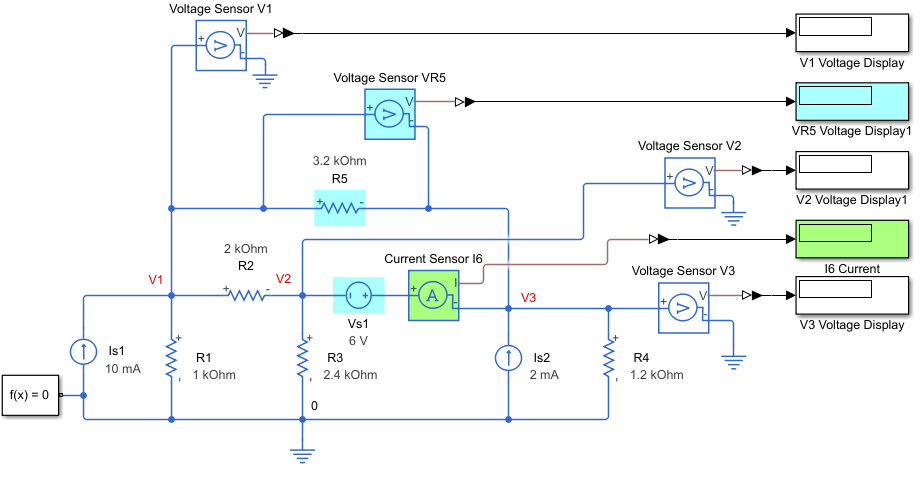

## References/Additional Info

***Electric Circuits***, James Kang, 1st ed. Cengage Learning, 2018